# Introduction

The goal for this project is to use the Fourier Series will be used to plot and determine characteristics of a signal. Characteristics such as if the periodic function is even or odd, or even real. The Fourier transform will be applied to a signal in order to plot and find the intensity and frequency of signals by converting them into the frequency domain. The same is done to analyze an audiofile in order to calculate the specific frequency of the piano-note given, All of this plotting and calculation is done in matlab, allowing one to effectively visualize signals and use the built in functions to do heavy computation with relative ease.

# Description

For part one of the project, we will calculate the fourier series of the two given periodic signals to determine their characteristics. Matlab in this question is used essentially as a calculator in order to calculation the summations of the given signals. These datapoints are then stored and plotted, making it easier for the student to graphically observe the fourier series and extract certain pieces of information.

For part two of this project, a given signal will be plotted alongside the DFT of the signal, using this to plot the signal in the frequency domain against time. in order to confirm the frequencies match up in magnitude and intensity to the given equation. The signal is then modified and the entire process is repeated to ensure knowledge of how to use the fourier transform, and confirm the results. After this, we plot the inverse Fourier transform using matlab's ifft() function, plotting the signal in time serves the purpose of confirming the Inverse Fourier Transform was done succesfully.

in the last part of this project the given audio file is dealt with, using matlab not only to play and read the sound wave, but to determine the frequency using the Fourier transform, by plotting the signal in the frequency domain against time.

## Theory background

The Fourier Series represents a periodic function as a sum of sines and cosine functions, comparable to a taylor series. Fourier series have many real world applications, such as processing signals using Fourier Analysis. Fourier series can also be used in Approximation theory, used to write functions for complex polynomials. An application that most of the people on earth use is audio compression, creating smaller audio files without sacrificing quality, or too much memory.

The Fourier Series results from a now proven theory where you can express any periodic function in terms of the sum of infinite sine and cosine waves. This series results from the expansion of a periodic function, which can result in turning infinite sine and cosine waves into rectangular wave, or any type of function you might want. The Series expansion results from the three coefficients that the fourier series use, noted below:


$$f(x) = A_{0} + \sum_{n=1}^{+\infty} a_{n}cos(\frac{nx\pi}{L}) +\sum_{n=1}^{+\infty} b_{n}sin(\frac{nx\pi}{L}) \\$$


f(x) is the function that is generated, the three coefficients are found as follows:


$$A_{0} = \frac{1}{2L}\int_{-L}^{L} \! f(x) \, \mathrm{d}x.$$



$$a_{n} = \frac{1}{L}\int_{-L}^{L} \! f(x)cos(\frac{nx\pi}{L}) \, \mathrm{d}x.$$



$$b_{n} = \frac{1}{L}\int_{-L}^{L} \! f(x)sin(\frac{nx\pi}{L}) \mathrm{d}x.$$


The first coefficient is essentially the average value of the function, while the two next coefficients directly relate to how much of the sine and cosine parts needed to generate the desired signal. Using these equations, any signal imaginable can be created, one can even use the fourier series to draw images. The Fourier Series has its place is other types of math,  making it possible to solve high order partial differential equations more efficiently.

The Fourier Transform is a method of decaying a function of time, into the frequency domain. This would mean that a musical tone can be expressed into their respective volume and frequency harmonics. The Fourier Transform, has its own fair share of real world applications, such as Telecommunication. The transformation has massively affected compression, as well as the method of sending data to be faster than once thought possible. Voice recognition also affectively implements the fourier transform in order to analyze the user's voice to verify the user for security purposes. In this project, the fourier transform is used to analyze both a mathematical signal, and an audio file to determine the frequency components.

The Fourier transform is derived from a fourier series when the period T approaches infinity.


$$x(t) = \sum_{n=-\infty}^{+\infty} c_{n}e^{jnw_{o}t}$$


The coefficient $c_{n}
$ given by:


$$c_{n} = \frac{1}{T}\int_{T}x(t)e^{-jnw_{o}t$$


This is rewritten as


$$Tc_{n} = \int_{T} x(t)e^{-jnw_{o}t}$$


An important step at this point is to realize that as T approaches infinity, the fundamental frequency ($\omega_{0} = \frac{2\pi}{T}$) becomes very small. The variable $\omega = n\omega_{o}$ is defined as the value becomes continuous due to T. The variable $X(\omega)= Tc_{n}$ then becomes defined, and results in the Forward Fourier Transform:


$$X(\omega) = \int_{-\infty}^{\infty} x(t)e^{-j\omega t}dt$$


The Inverse Fourier transform is discussed in a question later in the project, and the derivation comes similarly from the Forward Fourier Transform:


$$x(t) = \sum\limits_{n =  - \infty }^{ + \infty } {{c_n}{e^{jn{\omega _o}t}}}  = \sum\limits_{n =  - \infty }^{ + \infty } {T{c_n}{e^{jn{\omega _o}t}}} {1 \over T}$$


In this case, as T approaches infinity, T is replaced by the value $d\omega$ as $\omega_{o}$ becomes very small. At this point, the summation is replaced by an integral and the substitutions $\omega = n\omega0
$ and $X(\omega) = Tc_{n}$ are made to result in:


$$x(t) = \sum\limits_{n =  - \infty }^{ + \infty } {X(\omega ){e^{j\omega t}}} {{d\omega } \over {2\pi }} = {1 \over {2\pi }}\int\limits_{ - \infty }^{ + \infty } {X(\omega ){e^{j\omega t}}d\omega }$$


The Inverse Fourier transform accomplishes the reverse Fourier transform, resulting in a waveform from its Fourier coefficients. Similarly, the Inverse Fourier transform results in the reverse real world applications as it does in its process.

## 1 Fourier Series

Implement Matlab code for the periodic signals given by their Fourier Series approximation as follows:


$$x_1(t)=\sum_{k=-100}^{100} j k e^{-|k|}\ e^{jk\ \frac{2\pi}{50}\ t$$



$$x_2(t)=\sum_{k=-100}^{100}
\left|sin\left(\frac{k\pi}{2}\right)\right|
\ e^{jk\ \frac{2\pi}{50}\ t$$


## 2 Fourier Transform

The objective is to compute the Fourier Transform of input data, identify the frequency components in the spectrum and perform further analysis. All computations are done numerically, and signals are discrete in both time and frequency. The Discrete Fourier Transform (DFT) is computed using the Matlab function ﬀt(..). Fast Fourier Transform (FFT) is an algorithm for computing the Discrete Fourier Transform eﬃciently.

## 3 Edge Detection

Implement an edge detection algorithm and test on some images. Some example algorithms are: 

- Canny Edge Detection

- Gradient Operators

- Phase Stretch Transform 

To receive extra credit you must work independently, and the code must be yours. Some example images have been posted, but you must use your own images.

# Algorithm and Matlab Implementation

In order to calculate the summation in the fourier series below, two vectors are created, one for each signal. Both vectors are then calculated for every value from -$2\pi
$to $2\pi
$ by evaluating the sum. The sum is evaluated within the range -100 to 100 by using embedded for loops. These vectors are then plotted in a subplot, one subplot detailing the real parts of the signal, and the other representing the imaginary parts.

## 1 Fourier Series


$$x_1(t)=\sum_{k=-100}^{100} j k e^{-|k|}\ e^{jk\ \frac{2\pi}{50}\ t$$



$$x_2(t)=\sum_{k=-100}^{100}
\left|sin\left(\frac{k\pi}{2}\right)\right|
\ e^{jk\ \frac{2\pi}{50}\ t$$


Implement the sum as given by the above equations. Note that in Matlab, array indices are positive and start at 1. Deﬁne the negative coeﬃcients carefully. Plot the signals, and the real and imaginary part of the signals x1 (t) and x2 (t). 

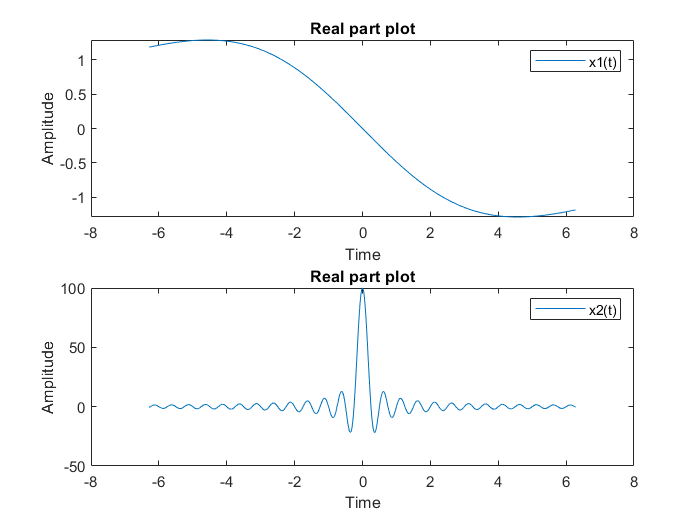

close
clear all
clc
%%Question 01 - Fourier Series 
t=-2*pi:0.01:2*pi; % Time period I chose to plot the signal on
%Two Embedded for loops to calculate each value of the signals
for i=1:length(t)
    x1(i)=0;
    for k=-100:100
        x1(i)=x1(i)+j*k*exp(-abs(k))*exp(j*k*2*pi*t(i)/50);
    end
    x2(i)=0;
    for k=-100:100
        x2(i)=x2(i)+abs(sin(k*pi/2))*exp(j*k*2*pi*t(i)/50);
    end
end
%Figure 1 - Subplot of the real parts of both signals
figure;
hold on % In order to plot more than one signal
subplot(2,1,1) % 1 by 2 array - position 1
plot(t,real(x1)); % Real part of x(t)
title('Real part plot');
legend('x1(t)');
xlabel('Time')
ylabel('Amplitude')
subplot(2,1,2) % Subplot 2
plot(t,real(x2)); % Plot real part of x2(t)
title('Real part plot');
legend('x2(t)');
xlabel('Time')
ylabel('Amplitude')
hold off

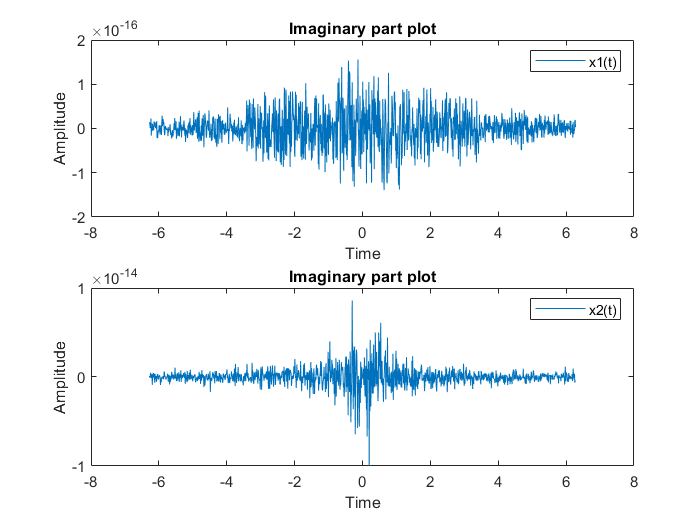

%Figure 2 - Subplot of the Imaginary parts of both signals
figure;
%Another 1 by 2 array of subplots
subplot(2,1,1)
plot(t,imag(x1)); %Imaginary part of x(t)
title('Imaginary part plot');
legend('x1(t)');
xlabel('Time')
ylabel('Amplitude')
subplot(2,1,2)
plot(t,imag(x2)); %Imaginary plot of x2(t)
title('Imaginary part plot');
legend('x2(t)');
ylabel('Amplitude')
xlabel('Time')

In each case, determine the following:

- Are the signals real?

- Are the signals even or odd?

Explain why.

The signal $x_{1}(t)$ is real as the imaginary part has such a small magnitude in comparison to the real part of the signal. The maximum of the imaginary part lies at around $1.5*10^{-16}$, while any value of the real part holds the scientific notation of$10^1$. This would mean the imaginary part is more than $10^{-16}$ times smaller than any value on the real portion of the function. Therefore, the imaginary part of the function is so small, that it holds no power of the real part of the function, therefore the signal is real.

The signal $x_{2}t$ is also real for the same reason, as the maximum value is less than $1*10^{-14}
$. The imaginary part of the signal is less than $10^{-14}
$ the value of any point of the real portion of the signal. Therefore, similar to the first case the imaginary portion of the signal is so small that it doesn't affect the signal at all, and $x_{2}t$ is real.

Visually, you can find out if a signal is even or odd. If a signal is even $x(t) = x(-t)$, similarly a signal is odd if $x(t) = -x(-t)$. Using this property, $x_{1}(t)$ is an odd signal, as the function seems as if it was reflected over the line y=x. Visually the property for odd signals hold true, as $x(t) = -x(-t)$ for this function as does the coefficients where $a_{k}$ is purely imaginary and odd. For signal $x_{2}t$, the signal is even, Visually the signal looks like it was reflected over the y axis - therefore $x(t) = x(-t)$, and the signal is even as $a_{k}$ is also real and even.

## 2 Fourier Transform

### (A) 

An example code DFTExample1.m is posted on the Blackboard. It computes the Discrete Fourier Transform (DFT) of a cosine function using the ﬀt(..) function. Figure 1 shows some plots generated from this code. Study this code and the results. Note that in the output array, positive frequencies are at the beginning and the negative frequencies start from the end. You can also search for ﬀt(..) in Matlab Help. It provides some examples.

### (B)

Implement Matlab code for each part as described below:

#### (i)

 Deﬁne the following signal in time and plot it:


$$s(t)\ =\ 
A_1 \cos(2\pi f_1 t)
\ +\ A_2 \sin(2\pi f_2 t),$$


where $A_1 = 10,\ 
A_2 = 3,\ 
f_1 = 10\ \text{HZ},\ 
f_2 = 40\ \text{HZ}$ .

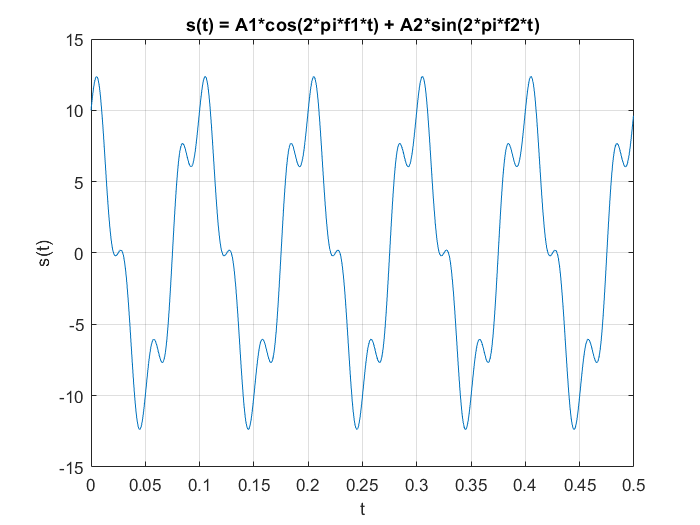

close
clear all
clc
%% PART 1
Fs = 2000; %Sampling frequency - This value was adjusted to see the signal
% better
T = 1/Fs; % sampling period
L = 1000; % signal length
t = (0:L-1)*T; % time vector considered - multiplication to keep the scale for accuracy
%defining properties of the signal and plotting the signal s in time domain
A1 = 10; A2 = 3; %Given Values
f1 = 10; f2 = 40;% Given Values
s = A1*cos(2*pi*f1*t) + A2*sin(2*pi*f2*t); %Equation of x(t)
figure; %Figure 1 - Defining the signal and plotting it
plot(t,s);
xlabel('t')
ylabel('s(t)')
title('s(t) = A1*cos(2*pi*f1*t) + A2*sin(2*pi*f2*t)')
grid on

#### (ii)

Compute the DFT *S(f)* of *s(t)* using the ﬀt(..) function. Plot the real and imaginary part of the DFT, and discuss the results. 

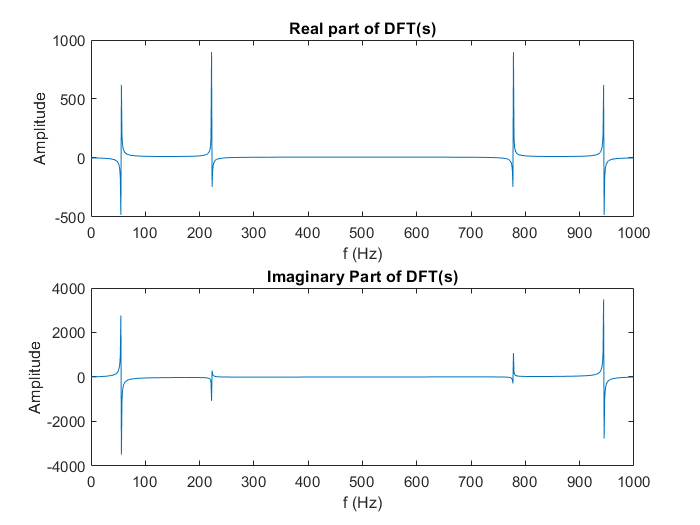

%% PART 2
% % DFT of s using matlab built-in function fft
Fs = 180; % 2000 Hz as previously used was too large, the value has been adjusted for this part of the assignment
T = 1/Fs; % sampling period
L = 1000; % signal length
t = (0:L-1)*T; % time vector considered Multiply by T to keep scale
s = A1*cos(2*pi*f1*t) + A2*sin(2*pi*f2*t);
S = fft(s); % DFT of s
figure;
%2 by 1 plot
subplot(2,1,1);
plot(t*Fs,real(S)); % Real part of the Dft of s - scaled using Fs
title('Real part of DFT(s)')
xlabel('f (Hz)')
ylabel('Amplitude')
subplot(2,1,2); % Imaginary part of the Dft of S
plot(t*Fs,imag(S));%Scaling x axis by Fs
title('Imaginary Part of DFT(s)')
xlabel('f (Hz)')
ylabel('Amplitude')

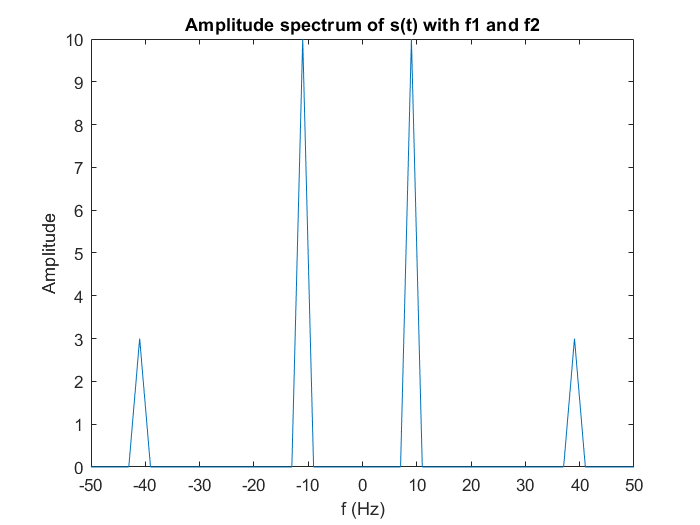

% PLotting the frequencies
Fs = 2000; %sampling frequency - This value was adjusted to see the signal
% better
T = 1/Fs; % sampling period
L = 1000; % signal length
t = (0:L-1)*T; % time vector considere
s = A1*cos(2*pi*f1*t) + A2*sin(2*pi*f2*t); %Equation
S = fft(s); % DFT of s
negative_positive_spectrum = (2*abs([S(L/2+2:end) S(1:L/2+1)]))/L; %Two sided spectrum equation on matlab
f=Fs/2*linspace(-1,1,L);%Scaling the x axis to be in terms of frequency
figure;
plot(f,negative_positive_spectrum)
title('Amplitude spectrum of s(t) with f1 and f2')
xlabel('f (Hz)')
ylabel('Amplitude')
xlim([-50 50])

As the real and imaginary parts of the DFT of s(t) is plotted, one can see that the imaginary part's plot has a much higher minimum and maximum on the Y axis than that of the real part. this is most probably coming from the imaginary term in the Fourier Transform of sin(x). One can view and believe this imaginary portion may overwhelm the real portions of the DFT at specific points. Actually, the real portion of the FFT represents information about the frequency and magnitude of the signals being transformed. The imaginary portion determines the phase shift of the corresponding frequencies, this effect can be viewed in some properties of the fourier transform below:

The amplitude is represented by$|\hat{f}(\omega)|$, and the phase is represented by$ \hat{f}(\omega)$ in the Fourier transform equation below.


$$f(\omega) = |\hat{f}(\omega)| e^{i\text{ arg}\ \hat{f}(\omega)}$$


This  results from a shift in the time domain, as a shift $t \mapsto t-a$ will result in a scaling by $e^{-i a \omega}$ in the frequency domain.

After adjusting the scaling of the fft() and plotting the frequency spectrum, the results are as expected, clearly seeing the amplitude of the sine and cosine signals of 3 and 10, as well as their corresponding frequencies of 40Hz and 10Hz respectively. This plot matches up with the original given equation, resulting in a successful fourier transform. 

#### (iii)

Remove the high frequency component, that is f2 from the spectrum by setting it to zero. Do this carefully for both positive and negative frequencies. Call this signal *G(f)*. Plot the spectrum. 

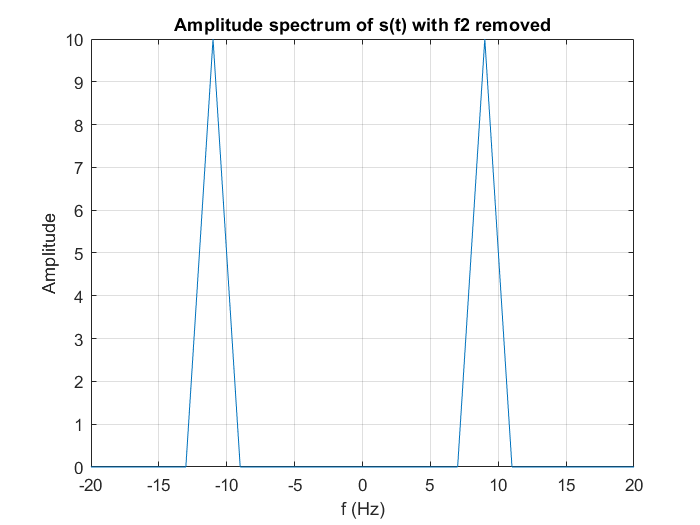

%PART 3
%removing the f2 component and plotting the rest of the spectrum
G =  fft(A1*cos(2*pi*f1*t)); % Sine(0) = 0 - Ignore the other half
figure
plot(f,(2*abs([G(L/2+2:end) G(1:L/2+1)]))/L);
%Two sided frequency spectrum
title('Amplitude spectrum of s(t) with f2 removed')
xlabel('f (Hz)')
ylabel('Amplitude')
xlim([-20 20]) % Better Visibility
grid on

The results are as expected in this spectrum, as value f2 goes to zero, and sine(0) = 0, essentially the second half of the signal becomes nonexistent. This would mean that only the magnitude and frequencies of the portion $A1*cos(2*pi*f1*t)$ where $f1=10 $ and$A1=10
$ will be seen , which is correctly represented by the spectrum plot above.

#### (iv)

Let *g(t)* be the inverse Fourier transform of *G(f)*. Compute *g(t)* using the function iﬀt(..) and plot the signal in time. Discuss the results.

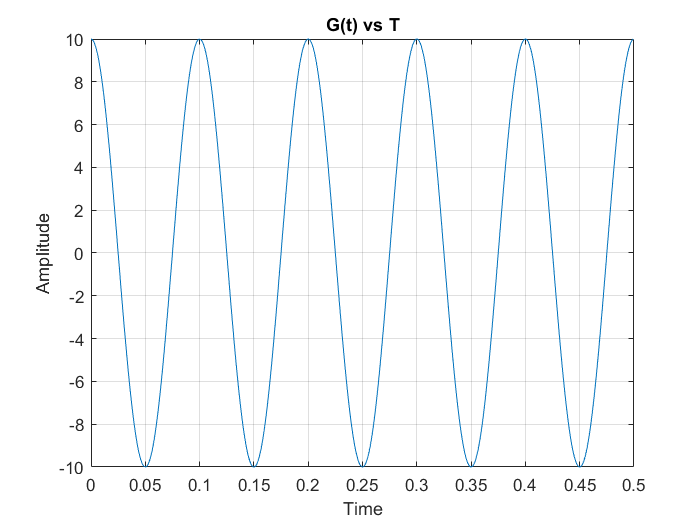

%PART 4
% obtaining g(t) using matlab built-in function ifft and plotting in time domain
figure
g = ifft(G);
plot(t,g);
xlabel('Time')
ylabel('Amplitude')
grid on
title('G(t) vs T')

The inverse Fourier Transform is used to convert signals from the frequency domain to the time domain. As we are going backwards in this Fourier transform, the original signal is being constructed using this function on a cosine. Due to the fact the original signal is being reconstructed, the expected signal from the ifft() is another cosine wave, therefore the experiment went as expected.

### (C) 

In this part you will read an input sound data ﬁle, with a single piano note, and determine its frequency from the spectrum:

#### (i)

Read the input sound wave ﬁle in PianoKey.wav, using the audioread(..) function. 

close
clear all
clc
filename = 'Pianokey.wav'; % Path
[y,Fs] = audioread(filename); % Using Fs to cut the signal to reduce noise
samples = [1.59*Fs,1.82*Fs]; %Bounds of the signal with the actual key sound - to reduce noise and ensure accuracy
[y,Fs] = audioread(filename, samples);%Loading in the cut signal

#### (ii)

Play it using the sound(..) function.

sound(y,Fs);

#### (iii)

Compute its DFT, using the ﬀt(..) function, and plot it. 

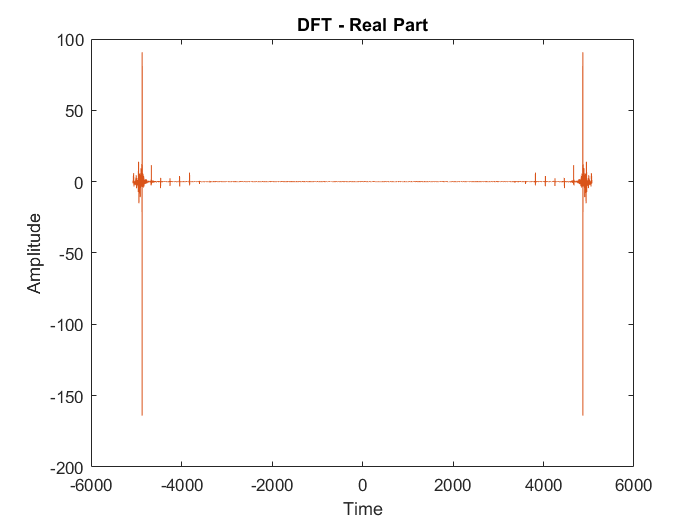

x = fft(y); %DFT
figure
title('DFT - Real Part')
xlabel('Time')
ylabel('Amplitude')
T = 1/Fs; % sampling period
L = length(y); % signal length
t = (-(L/2):(L-1)/2)*T; % time vector considered
plot(t*Fs,real(x)) %Scaling the x axis, plotting the real plot
title('DFT - Real Part')
xlabel('Time')
ylabel('Amplitude')

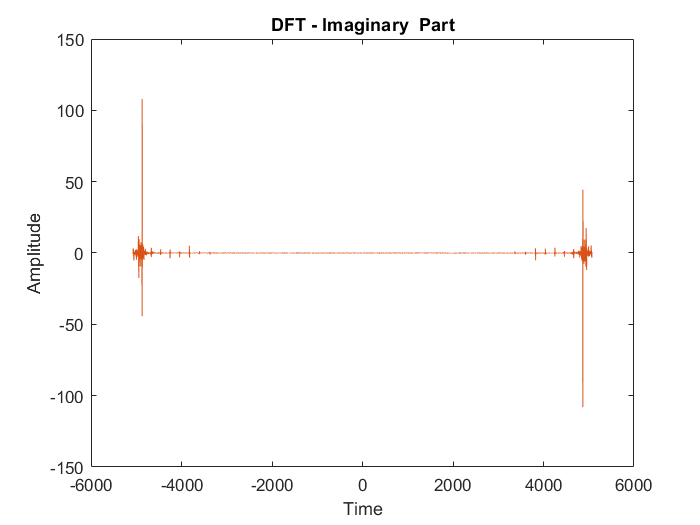

figure;
plot(t*Fs,imag(x)) %Scaling the x axis, plotting the imaginary plot
title('DFT - Imaginary  Part')
xlabel('Time')
ylabel('Amplitude')

#### (iv)

Determine the frequency of the piano key.

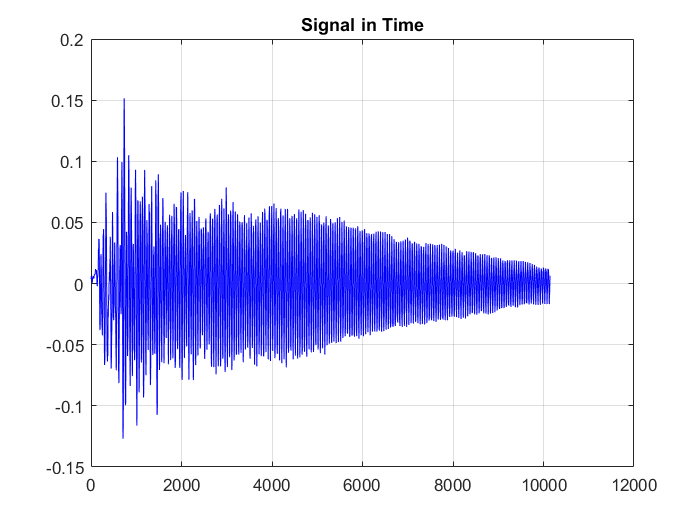

x = fft(y); %Plotting the values of the signal
figure
plot(y, 'b-');
grid on
title('Signal in Time');

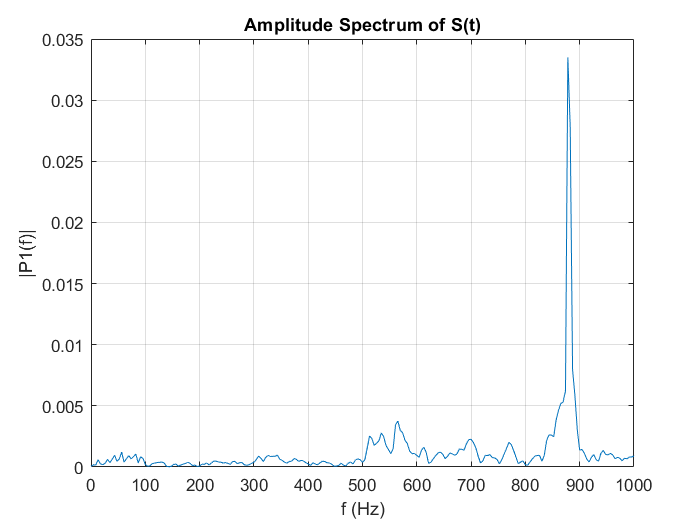

figure; 
T = 1/Fs; % sampling period
L = length(y); % signal length
t = (0:L-1)*T; % time vector considered
Y = x;
f = Fs*(0:(L/2))/L; %Scaling the X axis to maintain a correct frequency value using size of the signal
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);%Plotting the frquency spectrum
plot(f,P1); %Scaled x axis against the frequency spectrum
xlim([0 1000]) %Limiting the plot for clarity's sake
title('Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
grid on

The frequency was determined to be about 878Hz based on calculation. The nearest note that has a frequency is about 880 Hz, being the note $A_{5}$ on a piano. This is because 878 has the highest intensity on the plot, showing  that this is the note they are after, all that must be done at that point is to determine the value of the scaled X axis, found to be 878Hz, as there is an actual note to be found at this frequency, the experiment was succesful.

## 3 Edge Detection  

TODO: Detailed description of the algorithm you found, and matlab implementations.

% This will be submitted on a later date as per the due date is on Sunday

# Results and Conclusions

TODO: Analysis, plots, interpretations and numerical errors. How do the results compare with theory? Summarize your ﬁndings. 

For Part 1.1, $x_{1}(t)$ was found to be real and odd, using the coefficients from the properties of real and odd signals for the fourier series, where $a_{k}$ is purely imaginary and odd. This can be also seen visually as previously discussed. The signal was found to be real as the imaginary portion was so insignificant in comparison. For signal  $x_{2}t$ the signal was found to be real, as similarly the imaginary portion was so insignificant. In this case the coefficient $a_{k}$ was found to be real and even, and therefore the signal is even which also can be visually seen as discussed earlier.

For Part 1.2(B), the signal was plotted with an adjusted sampling frequency to view the signal clearly. In part (ii), the real and imaginary plots of the DFT are plotted. It was noticed that the imaginary plot has a much higher magnitude in comparison, this is seen to come from the sine term of the original equations, as it has an imaginary portion $j
$ which represents a shift in the time domain as previously discussed above. After this, the frequency spectrum was plotted, having completely correct values for amplitude. The same cannot be said for the frequencies, as the expected frequency of 40hz reads as 41Hz, and 10Hz reads as 9.09Hz. this numerical error may result from noise stemming from either the real or imaginary plots swaying the value. Next, the removal of the high frequency component, they essential removed the sine half of the signal - as expected, the newly plotted frequency spectrum does not have the magnitude or frequency of the sine portion. For the final portion of part B, the Inverse Fourier transform is plotted, appearing as a cosine signal as expected - The Inverse fourier transform recovers a function form its Fourier transform, reconstructing the original wave, therefore since it is a cosine wave, the expected wave applying an inverse fourier transform is another cosine wave, prooving to be a successful use of ifft().

For part C, the frequency was calculated at about 878Hz. Looking at the frequency of piano notes it was decided that this note is most probably $A_{5}$ at 880hz as the next note above or below is much farther away. This was done by cutting the audio to reduce excess noise, and using that sampling frequency to scale the X axis in order to read it as the correct frequency. From there, the peak is analyzed, and the x coordinate was found ot be 878hz, the frequency. Because there is a note at the frequency found, the experiment prooved to be rather successfull.

# References and Citations

Oppenheim, Alan V., et al. *Signal and Systems*. Prentice Hall of India, 1990.

Pinkus, Allan, and Samy Zafrany. *Fourier Series and Integral Transforms*. Cambridge University Press, 1997.